# RX Anomaly score on Scattering

## First we try calculating the scores on the whole image



regionPixels = find(labelscyto > 0);
R = Scattering;
for i = (1:13)
    R(:,:,i) = wiener2(R(:,:,i),[5 5]); % apply denoising to the bands
end

%scores with denoising
rxScoresprep = anomalyRX(R); 

%scores without denoising
rxScores = anomalyRX(Scattering);

rxScores = im2uint8(rescale(rxScores));
rxScoresprep = im2uint8(rescale(rxScoresprep));

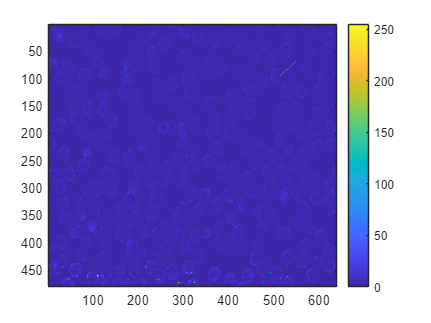

% set up a masked version that only shows values wihtin cells
masked = rxScores;
masked(labelscyto == 0) = 0;
maskedp = rxScoresprep;
maskedp(labelscyto == 0) = 0;
imagesc(masked)
colorbar

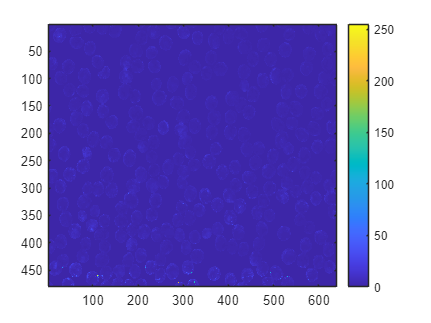

imagesc(maskedp) %without denoising, we seem to have lost a lot of information
colorbar

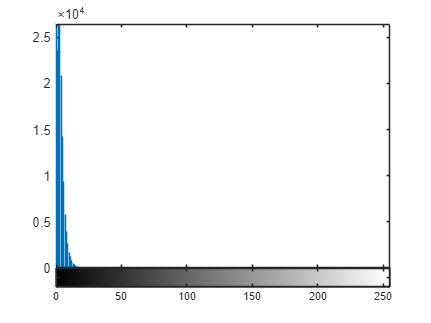

imhist(masked) 

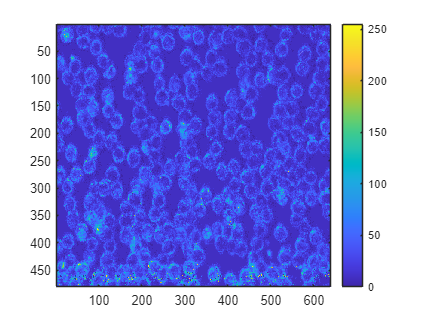

%since values in general seem very low we will have to reduce the range
extremes = 30;
rxScores(rxScores>extremes) = 0;
rxScoresprep(rxScoresprep>extremes) = 0;
rxScores = im2uint8(rescale(rxScores));
rxScoresprep = im2uint8(rescale(rxScoresprep));

masked = rxScores;
masked(labelscyto == 0) = 0;
maskedp = rxScoresprep;
maskedp(labelscyto == 0) = 0;

imagesc(rxScores)
colorbar

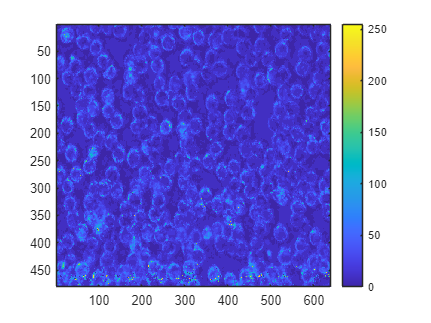

imagesc(rxScoresprep)
colorbar

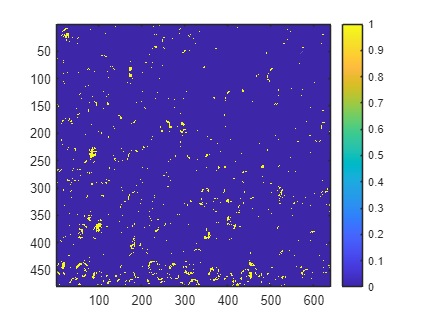

%seems better to proceed with denoised, since it favors less the noisy
%cells
thresh= maskedp > 60; 
imagesc(thresh)
colorbar

## Now we try to automate candidate selection

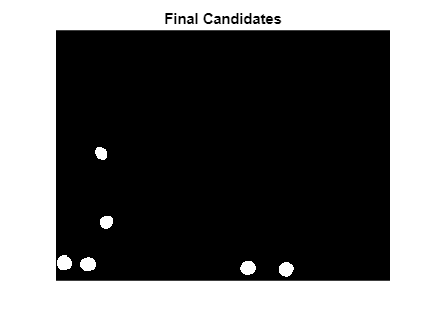


numLabels = max(labelscyto(:));
selectedMask = zeros(size(labelscyto));

% Loop through every label
for label = 1:numLabels
    % Get a binary mask for the current label
    labelMask = (labelscyto == label);
    
    % Count the total number of pixels in this label
    totalPixels = sum(labelMask(:));
    
    % sum the score of anomalous pixels in this label
    numAnomalous = sum(thresh(labelMask));
    
    % Calculate the final score of anomalous pixels in this label
    anomalyPercentage = (numAnomalous / totalPixels) * 100;
    
    % If the anomaly score exceeds the threshold, keep this label
    if numAnomalous > 130
        selectedMask(labelMask) = label;
    end
end
imshow(selectedMask);
title('Final Candidates');

## Now we try to minimimize background pixels when calculating rxScore


[X, Y, Bands] = size(Scattering);

% Get the total number of labels in the segmentation mask
numLabels = max(labelscyto(:));

% Cap MaxPixelsPerLabel at 800 (observed maximum amount of pixels per cell)
MaxPixelsPerLabel = min(800, ceil((X * Y) / numLabels));


spectraMatrix = zeros(numLabels, MaxPixelsPerLabel, Bands);

% Loop through each label
for label = 1:numLabels
    % Get a binary mask for the current label
    labelMask = (labelscyto == label);
    
    % Find the indices of the pixels in this label
    [row, col] = find(labelMask);
    
    % Limit the number of pixels to MaxPixelsPerLabel
    numPixels = min(length(row), MaxPixelsPerLabel);
    row = row(1:numPixels);
    col = col(1:numPixels);
    
    % Extract the spectra of these pixels
    pixelSpectra = zeros(numPixels, Bands); 
    for i = 1:numPixels
        % Get the spectra for each pixel using row, col indices
        pixelSpectra(i, :) = Scattering(row(i), col(i), :);
    end
    
    spectraMatrix(label, 1:numPixels, :) = pixelSpectra;
end


disp(size(spectraMatrix));% each row represents a different cell

   266   800    13



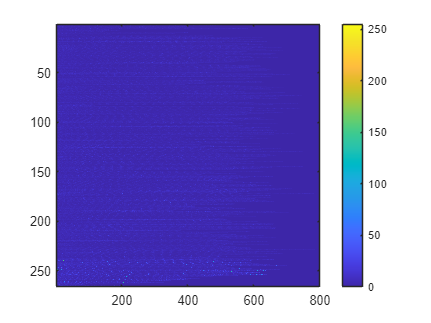

rxScores = anomalyRX(spectraMatrix);

rxScores = im2uint8(rescale(rxScores));
imagesc(rxScores)
colorbar

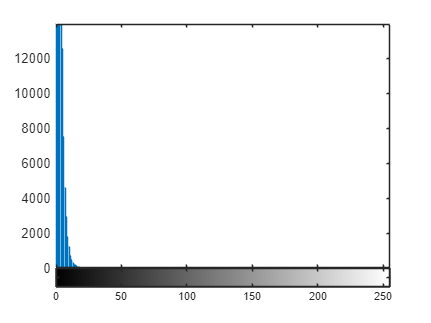


imhist(rxScores) %trying to find good threshold to discord extremes

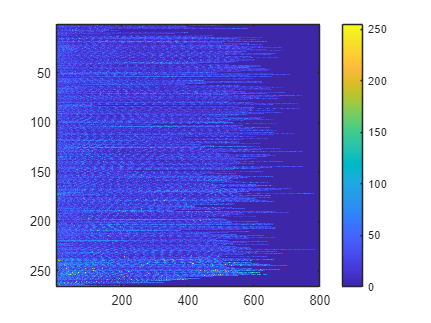


extremes = 30;
rxScores(rxScores>extremes) = 0;
rxScores = im2uint8(rescale(rxScores));
imagesc(rxScores)
colorbar

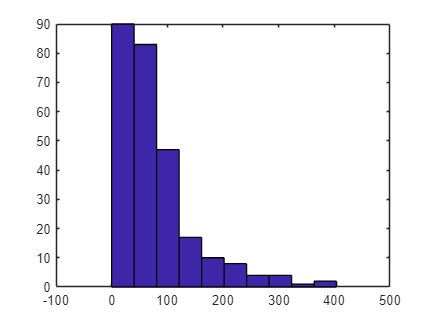

thresh = rxScores>50;

%Calculate the anomaly score of every cell
threshs = sum(thresh,2);
hist(threshs)

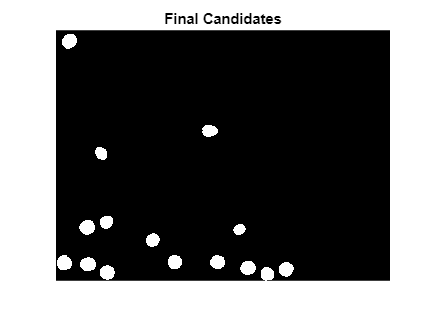


selectedMask = zeros(size(labelscyto));
%Loop through every score and discard below the threshold
for label = 1:numLabels
    labelMask = (labelscyto == label);
    if threshs(label) > 225  
        selectedMask(labelMask) = label;
    end
end
imshow(selectedMask);%noisy cells very favored
title('Final Candidates');

%results in this one seem very consistent with full image